addpath Tool
addpath Informs
addpath Model
addpath Data 
addpath ValidationFunctions

load('coInform.mat')

T = InformContainer{18}.T;
T = gsua_load(T);

T.Properties.CustomProperties.output = [9, 10, 15]; 
T.Properties.CustomProperties.Domain = [0, 743];

y = gsua_deval(T.Nominal',T,0:743);

close all
figure
for i = 1:3
    subplot(3,1,i)
    plot(ydata(i,:))
    hold on
    grid on
    plot(y(i,:))
end
legend('real data', 'simulation', 'Location','best','box','off')


D = 685;
T.Nominal(end)=607;    
opt = T.Properties.CustomProperties.copt;
     
% Create extension for saving difussion systems
Range2 = T.Properties.CustomProperties.creator.Range(1:end,:);
opt.rnames = T.Properties.RowNames;
        
opt.out_names = T.Properties.CustomProperties.Vars;
opt.range = Range2;    
opt.action = 2;
opt.domain = [0 D-1];
T.Properties.CustomProperties.copt = opt;
T.Properties.CustomProperties.Domain = [0 D-1];
xdata = 0 : D - 1;  
xdata2 = 0 : 743; 
T.Properties.CustomProperties.output = [9, 10, 15]; 
      
gsua_deval(T.Nominal', T, xdata);

Setting environment to work with user-defined function


copyfile nextTable.mat nextTableOriginal.mat    
load("nextTable.mat", 'T')
    
if  any(strcmp("reg", T.Properties.RowNames))
    T{'reg', 'Nominal'} = 0;
end
          
T.Properties.CustomProperties.output = [9, 10, 15]; 
    
ysim1 = [];
ysim2=[];
n = 100;
a=0.2;
b=0.3;
params1 = (b-a)*rand(n,1)+a;

a=0.01;
b=0.2;
params2 = (b-a)*rand(n,1)+a;


for i = 1:n
    load("nextTableOriginal.mat", 'T')

    opt = T.Properties.CustomProperties.copt;
     
    % Create extension for saving difussion systems
    Range2 = T.Properties.CustomProperties.creator.Range(1:end,:);
    opt.rnames = T.Properties.RowNames;            
    opt.out_names = T.Properties.CustomProperties.Vars;
    opt.range = Range2;    
    opt.action = 2;
    opt.domain = [0 D-1];
    T.Properties.CustomProperties.copt = opt;
    T.Properties.CustomProperties.output = [9, 10, 15]; 
    T.Nominal(end)=607; 
    Nominal = [T.Nominal(1:4); params1(i,1);T.Nominal(6:end)]';
    ysim1(i,:,:) = gsua_deval(Nominal, T, xdata);


    load("nextTable.mat", 'T')
    T.Properties.CustomProperties.Domain = [0 length(xdata2)-1];
    T.Properties.CustomProperties.output = [9, 10, 15]; 
    T.Nominal(end)=684; 
    Nominal = [T.Nominal(1:4); params2(i,1);T.Nominal(6:end)]';
    ysim2(i,:,:) = gsua_deval(Nominal, T, xdata2);
end 

Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting en

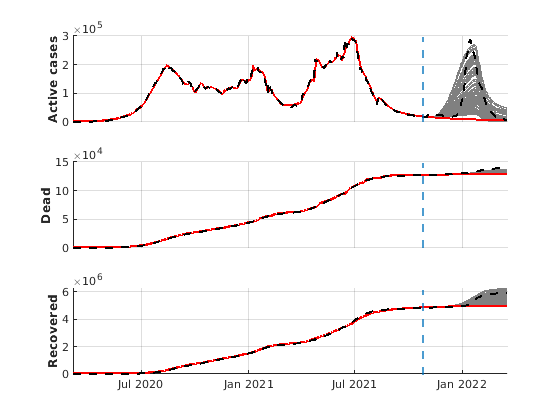

d1 = datetime('06/03/2020','InputFormat','dd/MM/uuuu');
days = d1:1:d1+743;
Names = ["Active cases", "Dead", "Recovered"];


close all
figure
for i = 1:3
    subplot(3,1,i)
    hold on
    grid on
    plot(days, squeeze(ysim2(:,i,:))','color', [.5 .5 .5],'LineWidth',1)
    plot(days, y(i,:),'r','LineWidth',1.5)
    plot(days, ydata(i,:),'--k','LineWidth',1.5)
    if i<3
        set(gca,'XColor', 'none','XColor','none')
    end
    xlim([d1 d1+743])
    xline(600,'--','color',[0 0.4470 0.7410],'LineWidth',1.5)
    ylabel(Names(i),'fontweight','bold')
end